## Tarea 3

## Santiago Fernández Sáenz - C22943 

## Félix Madrigal Mora - C24459

### **Desarrollo**

**1.**$\texttt{[MATLAB]}$ Considere los siguientes tres algoritmos para obtener la factorización QR de una matriz $$A$$:

- Ortogonalización de Gram-Schmidt (inestable).

- Ortogonalización de Gram-Schmidt (estable).

- Triangularización de Householder.

**a)**

function [Q, R] = qr1(A)

    %size nos permite obtener las dimensiones de A
    [m, n] = size(A);
    Q = zeros(m, n); % Inicializamos la matriz Q
    R = zeros(n, n); % Inicializamos la matriz R

    for j = 1:n
        %vj se toma como la columna j de la matriz A
        vj = A(:, j); 
        
        for i = 1:j-1
            %calculamos la proyeccion
            R(i, j) = Q(:, i)' * A(:, j);
            vj = vj - R(i, j) * Q(:, i);
        end
        
        % Normalizar el vector vj para obtener qj
        R(j, j) = norm(vj);
        Q(:, j) = vj / R(j, j);
    end
end

**b)**

function [Q, R] = qr2(A)

    %size nos permite obtener las dimensiones de A
    [m, n] = size(A);
    Q = zeros(m, n); % Inicializamos la matriz Q
    R = zeros(n, n); % Inicializamos la matriz R
    V = A;

    for i = 1:n

        R(i, i) = norm(V(:, i));
        Q(:, i) = V(:, i) / R(i, i);

        for j = (i + 1):n

            R(i, j) = Q(:, i)' * V(:, j);
            V(:, j) = V(:, j) - R(i, j) * Q(:, i);
        end
    end
end

**c)**

function [Q, R] = qr3(A)

    %size nos permite obtener las dimensiones de A
    [m, n] = size(A);
    Q = zeros(m, n); % Inicializamos la matriz Q
    R = A;
    %es la matriz de identidad de tamaño mxm
    M = eye(m);

    for j = 1:n
         
        x = R(j:m, j);
        %creamos el vector e1
        e1 = zeros(length(x), 1);
        e1(1) = 1;
        
        vj = sign(x(1)) * norm(x) * e1 + x;
        vj = vj / norm(vj); 
        R(j:m, j:n) = R(j:m, j:n) - 2 * vj * (vj' * R(j:m, j:n));
        M(j:m, :) = M(j:m, :) - 2 * vj * (vj' * M(j:m, :));
    end

    Q = M';
end

**d)**

**¿Se cumple que A = QR?**

Técnicamente si, ya que note que las diferencias dan muy cercanas a 0, la razón por la cual no dan 0 se podría atribuir a alguna inestabilidad del modelo o bien la precisión de la máquina.

**¿Se cumple que Q es ortogonal?**

De nuevo, si, por la misma razón, al calcular la norma ortogonal, los resultados dan muy cercanos a 0.

**Determine si algún algoritmo es mejor que otro.**

En cuanto a precisión es mejor el algoritmo 1, pero en cuanto a aproximar la matriz ortogonal es mejor el algoritmo 3

m = 20;
A = rand(m);
n = 20;
[Q1, R1] = qr1(A);
[Q2, R2] = qr2(A);
[Q3, R3] = qr3(A);

norma_dif1 = norm(A - Q1* R1);
norma_dif2 = norm(A - Q2 * R2);
norma_dif3 = norm(A -Q3 * R3);

norma_ortogonal1 = norm(Q1* Q1' -eye(m));
norma_ortogonal2 = norm(Q2 * Q2' - eye(m));
norma_ortogonal3 = norm(Q3 *Q3' -eye(m));


Los resultados de qr1 son:


fprintf('Los resultados de qr1 son:\n');

norma_dif1 = 0.00000000000000068596


fprintf('norma_dif1 = %.20f\n', norma_dif1);

norma_ortogonal1 = 0.00000000000012049494



fprintf('norma_ortogonal1 = %.20f\n\n', norma_ortogonal1);


Los resultados de qr2 son:


fprintf('Los resultados de qr2 son:\n');

norma_dif2 = 0.00000000000000066635


fprintf('norma_dif2 = %.20f\n', norma_dif2);

norma_ortogonal2 = 0.00000000000001514657



fprintf('norma_ortogonal2 = %.20f\n\n', norma_ortogonal2);


Los resultados de qr3 son:


fprintf('Los resultados de qr3 son:\n');

norma_dif3 = 0.00000000000000256739


fprintf('norma_dif3 = %.20f\n', norma_dif3);

norma_ortogonal3 = 0.00000000000000128311



fprintf('norma_ortogonal3 = %.20f\n\n', norma_ortogonal3);

**e)**


m = 20;
A = hilb(m);
n = 20;
[Q1, R1] = qr1(A);
[Q2, R2] = qr2(A);
[Q3, R3] = qr3(A);
[Qm, Rm] = qr(A);


norma_dif1_H = norm(A - Q1 * R1);
norma_dif2_H = norm(A - Q2 * R2);
norma_dif3_H = norm(A - Q3 * R3);
norma_dif_m = norm(A - Qm * Rm);

norma_ortogonal1_H = norm(Q1 * Q1' - eye(m));
norma_ortogonal2_H = norm(Q2 * Q2' - eye(m));
norma_ortogonal3_H = norm(Q3 * Q3' - eye(m));
norma_ortogonal_m = norm(Qm * Qm' - eye(m));


Los resultados de qr1 son:


fprintf('Los resultados de qr1 son:\n');

norma_dif1 de Hilbert = 0.0000000000000007


fprintf('norma_dif1 de Hilbert = %.16f\n', norma_dif1);

norma_ortogonal1 de Hilbert = 0.0000000000001205



fprintf('norma_ortogonal1 de Hilbert = %.16f\n\n', norma_ortogonal1);


Los resultados de qr2 son:


fprintf('Los resultados de qr2 son:\n');

norma_dif2 de Hilbert = 0.0000000000000007


fprintf('norma_dif2 de Hilbert = %.16f\n', norma_dif2);

norma_ortogonal2 = 0.0000000000000151



fprintf('norma_ortogonal2 = %.16f\n\n', norma_ortogonal2);


Los resultados de qr3 son:


fprintf('Los resultados de qr3 son:\n');

norma_dif3 de Hilbert = 0.00000000000000256739


fprintf('norma_dif3 de Hilbert = %.20f\n', norma_dif3);

norma_ortogonal3 de Hilbert = 0.0000000000000013



fprintf('norma_ortogonal3 de Hilbert = %.16f\n\n', norma_ortogonal3);


Los resultados de qr de matlab son:


fprintf('Los resultados de qr de matlab son:\n');

norma_dif de matlab de Hilbert = 0.0000000000000004


fprintf('norma_dif de matlab de Hilbert = %.16f\n', norma_dif_m);

norma_ortogonal de matlab de Hilbert = 0.0000000000000013



fprintf('norma_ortogonal de matlab de Hilbert = %.16f\n\n', norma_ortogonal_m);

En este caso es difícil decidir que algoritmo es mejor, ya que el primero se podría clasificar como el peor ya que el error de la norma indica que Q no es ortogonal, sin embargo el algoritmo 2 es mejor en la aproximación a la matriz Hilbert, pero el algoritmo 3 y el algoritmo de Matlab el error de la norma ortogonal da muy pequeño y la aproximación de la matriz es buena pero no mejor que el segundo algoritmo, de igual manera si hubiera que escoger uno creo que lo mejor es el de Matlab ya que obtiene resultados bastante buenos en ambas normas.

**2. ** $[\texttt{MATLAB}]$ En esta pregunta se deben usar los comandos de factorización propios de $\texttt{MATLAB} (\texttt{qr(A)}, \texttt{lu(A)}, \texttt{svd(A)}, \texttt{chol(A)})$. Defina $\texttt{m=12}$, $\texttt{x = ones(m,1)}$, $\texttt{A = hilb(m)}$, $\texttt{b = A*x}$. Buscamos resolver el sistema de ecuaciones $$Ax=b$$ mediante estas factorizaciones. Note que la solución exacta es $$x=[1,\ldots,1]^T$$ y denotamos por $$\hat{x}$$ la solución aproximada numéricamente.

Inicialmente, definimos las variables solicitadas.

format long
m = 12;
x = ones(m, 1);
A = hilb(m);
b = A * x;

**a)**

Para ver el número de condición, se tiene lo siguiente:

condicion = cond(A);
fprintf('El número de condición es: %.12f\n', condicion);

El número de condición es: 16211639047474996.000000000000


El número de condición de una matriz indica el nivel de presición al resolver un sistema de ecuaciones $$Ax=b$$, en particular, se puede afirmar que el resultado anterior es alto debido a que el número de condición de la matriz $A$ posee 17 dígitos no decimales, por lo cual, esto indica que se perderá presición de salida al resolver el sistema de ecuaciones.

Con los casos a resolver a continuación, es importante recordar que los algoritmos estudiados en clase (QR, Cholesky y descomposición en valores singulares) son estables hacia atrás, entonces, por teorema, su error relativo es de orden:


$$O(\varepsilon_m \cdot K(x))$$


en donde $\varepsilon_m$ es la presición de la máquina y $K(x)$ el número de condición.

En el caso de la factorización LU es aún más grave, pues hay que añadir un factor de crecimiento al error relativo:


$$O(\varepsilon_m \cdot K(x) \cdot 2 ^ {m - 1})$$


En donde $m$ es la cantidad de filas en una matriz cuadrada, es decir, para el caso concreto que se desarrolla en este ejercicio, el error relativo es de orden:


$$O(\varepsilon_m \cdot K(x) \cdot 2 ^ {11})$$


**b)**

Calculamos la factorización correspondiente:

[L, U, P] = lu(A);

Resolvemos el sistema de ecuaciones, como:


$$PA = LU \wedge Ax = b$$



$$\Longrightarrow P A x = P b$$


entonces, para calcular el error coupamos de la función [norm](https://la.mathworks.com/help/matlab/ref/norm.html), se sigue que el resultado es:

% Iniciamos calculando los vectores uno a uno
y = P * b;
y = L \ y;

% Calculamos el sistema
xhat1 = U \ y;

% Obtenemos el error
error_palu = norm((x - xhat1), 2);
fprintf('El error de resolver el sistema de ecuaciones con la factorización PA = LU es: %.12f\n', error_palu);

El error de resolver el sistema de ecuaciones con la factorización PA = LU es: 0.575664393204


**c)**

Procedemos de forma similar con la factorización QR:

% Se calcula la factorización
[Q, R] = qr(A);

% Calculamos el sistema
y = Q \ b;
xhat2 = R \ y;

% Obtenemos el error
error_qr = norm((x - xhat2), 2);
fprintf('El error de resolver el sistema de ecuaciones con la factorización QR es: %.12f\n', error_qr);

El error de resolver el sistema de ecuaciones con la factorización QR es: 0.764918203289


**d)**

Similarmente, con la factorización de Cholesky obtenemos el resultado:

% Factorización de Cholesky
L = chol(A);

% Se calcula el sistema
y = L' \ b;
xhat3 = L \ y;

% Obtenemos el error
error_chol = norm((x - xhat3), 2);
fprintf('El error de resolver el sistema de ecuaciones con la factorización de Cholesky es: %.12f\n', error_chol);

El error de resolver el sistema de ecuaciones con la factorización de Cholesky es: 0.586397446491


**e)**

Se procede análogamente con la descomposición en valores singulares, en este caso se requiere la pseudo-inversa de S con la función [pinv](https://la.mathworks.com/help/matlab/ref/pinv.html):


$$A = U S V ^ T \wedge Ax = b$$



$$\Longrightarrow U ^ T A x = U ^ T b$$



$$\Longrightarrow S V ^ T x = U ^ T b$$



$$\Longrightarrow x = V S ^ {-1} U ^ T b$$


% Se calcula la descomposición en valores singulares
[U, S, V] = svd(A);

% Se calcula el término de la derecha
y = U' * b;

% Se obtiene la pseudo-inversa de S
S_inversa = pinv(S);

% El sistema de ecuaciones
xhat4 = V * S_inversa * y;

% Obtenemos el error
error_svd = norm((x - xhat4), 2);
fprintf('El error de resolver el sistema de ecuaciones con svd es: %.12f\n', error_svd);

El error de resolver el sistema de ecuaciones con svd es: 0.004190573416


**f)**

El error es considerablemente grande en todos los casos calculados, sin embargo, al usar la descomposición en valores singulares se obtuvo el menor error de todos los métodos, este se considera aceptable ya que el error muestra una presición de 2 decimales, lo cual es particularmente bueno considerando el número de condición de la matriz A.

**g)**

Calculamos la aproximación de rango 9, para esto se tomó de referencia el código expuesto en el video de SVD Matlab que el profesor otorgó.

% Obtenemos los valores singulares
valSing = diag(S);

% Definimos la aproximación correspondiente
rango_aprox = 0;

% Iteramos para obtener el rango deseado
for i = 1:9
    rango_aprox = rango_aprox + (valSing(i) * U(:, i) * V(:, i)');
end

% Ahora, extraemos los valores singulares de la aproximación de rango mayor
[U_aprox, S_aprox, V_aprox] = svd(rango_aprox);

% Obtenemos el primer término
y = U_aprox' * b;

% Se obtiene la pseudo-inversa de S
S_inversa = pinv(S_aprox);

% El sistema de ecuaciones
xhat_rango = V_aprox * S_inversa * y;

% Obtenemos su error
error_rango = norm((x - xhat_rango), 2);
fprintf('El error de resolver el sistema de ecuaciones con la aproximación de rango 9 es: %.12f\n', error_rango);

El error de resolver el sistema de ecuaciones con la aproximación de rango 9 es: 0.000006885025


El error mejora significativamente con la aproximación de rango 9, este ofrece una presición de 5 decimales, lo cual supera a todos los métodos probados anteriormente. Esto se debe a los resultados de la reducción del rango en los valores singulares:

% Comprobamos los valores singulares de las 2 matrices
disp(diag(pinv(S_aprox)));

   1.0e+09 *

   0.000000000556988
   0.000000002629674
   0.000000022352088
   0.000000268650220
   0.000004290205107
   0.000089578785012
   0.002449553820979
   0.089058212897343
   4.440566925397238
                   0
                   0
                   0



disp(diag(pinv(S)));

   1.0e+13 *

   0.000000000000056
   0.000000000000263
   0.000000000002235
   0.000000000026865
   0.000000000429021
   0.000000008957879
   0.000000244955382
   0.000008905821296
   0.000444056721181
   0.032140399136485
   3.775111506531559
                   0



Debido al número de condición de la matriz A, sabemos que esta resulta en una pérdida de presición importante, lo cual se reduce al bajar el rango de la matriz, pues se "eliminan" los valores singulares más grandes de la matriz original, siendo sustituidos por 0 debido a la aproximación, esto crea mayor presición a la hora de calcular la svd, lo cual resulta en una reducción del error.

**3.**

**a) **

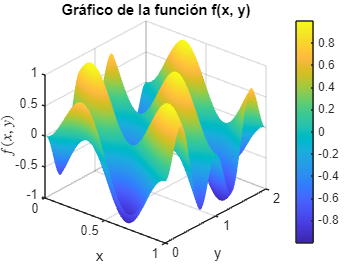

%vectores
x = linspace(0, 1, 100);
y = linspace(0, 2, 200);

%malla de puntos equidistantes
[xx, yy] = meshgrid(x, y);

% definimos la funciona dada para poder graficar
f = @(x, y) sin(2*pi*(x+y)) .* sin(pi*(x-y));


figure;
surf(xx, yy, f(xx, yy));
% aplica un sombreado mas suave
shading interp; 
%se encarga de agregar una barra de colores para hacer alusión a los valores
colorbar; 
%permite manipular el angulo de la vista
view(40, 30); 
xlabel('x' );
ylabel('y');
zlabel('$f(x, y)$', 'Interpreter', 'latex');
title('Gráfico de la función f(x, y)'); 
grid on;

**b) **

% matriz
zz = f(xx, yy);

%realizamos la descomposición en valores singulares y se guardan
[U, S, V] = svd(zz);
valsing = diag(S);

% se calculan las aproximaciones de los 4 rangos pedidos
zz1 = valsing(1) * U(:, 1) * V(:, 1)';
zz2 = zz1 + valsing(2) * U(:, 2) * V(:, 2)';
zz3 = zz2 + valsing(3) * U(:, 3) * V(:, 3)';
zz4 = zz3 + valsing(4) * U(:, 4) * V(:, 4)';


figure;
subplot(2, 2, 1);
surf(xx, yy, zz1);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz1$', 'Interpreter', 'latex');
title('Aproximación zz1'); 
grid on;

subplot(2, 2, 2);
surf(xx, yy, zz2);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz2$', 'Interpreter', 'latex');
title('Aproximación zz2'); 
grid on;

subplot(2, 2, 3);
surf(xx, yy, zz3);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz3$', 'Interpreter', 'latex');
title('Aproximación zz3'); 
grid on;

subplot(2, 2, 4);
surf(xx, yy, zz4);
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$zz4$', 'Interpreter', 'latex');
title('Aproximación zz4'); 
grid on;


% ahora graficamos el error absoluto
figure;
subplot(2, 2, 1);
surf(xx, yy, abs(zz - zz1));
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz1|$', 'Interpreter', 'latex');
title('Error zz1'); 
grid on;

subplot(2, 2, 2);
surf(xx, yy, abs(zz - zz2));
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz2|$', 'Interpreter', 'latex');
title('Error zz2');
grid on;

subplot(2, 2, 3);
surf(xx, yy, abs(zz - zz3));
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz3|$', 'Interpreter', 'latex');
title('Error zz3');
grid on;

subplot(2, 2, 4);
surf(xx, yy, abs(zz - zz4));
shading interp;
colorbar;
view(40, 30);
xlabel('x');
ylabel('y');
zlabel('$|zz - zz4|$', 'Interpreter', 'latex');
title('Error zz4');
grid on;

Conforme el rango se incrementa se puede notar una mejora en la aproximación, llegando prácticamente al mismo grafico de la función en el rango 4. Además en los gráficos de los errores absolutos ocurre algo similar, conforme se aumenta el rango el error va disminuyendo ya que la aproximación cada vez es mejor, de igual manera todos los errores son bastante pequeños por lo que se obtiene una buena aproximación mediante la descomposición en valores singulares.

**c)**

El rango de $zz$ se puede obtener usando rank

disp(rank(zz));

     4



Podemos comprobar que se cumpla que es de rango 4 numéricamente y ademas obtener los valores singulares que se piden

%creamos un vector fila sobre el cual vamos a iterar, es del tamaño de la
%cantidad de valores singulares mayores a 0
rango = ones(1, sum(valsing > 0));

for j = 1:length(rango)
    if valsing(j) > 0
        rango(j) = valsing(j);
    end
end
disp(valsing)

  35.791933448753497
  35.440972052131968
  35.090062695868767
  35.090062695868752
   0.000000000000032
   0.000000000000030
   0.000000000000023
   0.000000000000020
   0.000000000000018
   0.000000000000015
   0.000000000000013
   0.000000000000013
   0.000000000000012
   0.000000000000012
   0.000000000000012
   0.000000000000011
   0.000000000000011
   0.000000000000010
   0.000000000000010
   0.000000000000008
   0.000000000000008
   0.000000000000008
   0.000000000000008
   0.000000000000008
   0.000000000000007
   0.000000000000007
   0.000000000000007
   0.000000000000006
   0.000000000000006
   0.000000000000006
   0.000000000000006
   0.000000000000005
   0.000000000000005
   0.000000000000005
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.000000000000004
   0.00000000

Entonces note que los valores singulares obtenidos solo hay 4 positivos los demás son muy pequeños por lo que en este caso al ser numéricamente se podría considerar que son 0 ya que se acerca a la precisión de la maquina y la aproximación es bastante buena, así podemos asegurar que es de rango 4 es decir solo tenemos 4 valores singulares, los otros son 0.

**d)**

Dada la función:


$$\[ f(x, y) = \sin(2\pi(x + y)) \sin(\pi(x - y)) \]$$


Podemos reescribirla de la siguiente manera:


$$\[ f(x, y) = \frac{1}{2} [\sin(2\pi x)\cos(2\pi y) + \cos(2\pi x)\sin(2\pi y)] \cdot \frac{1}{2} [\sin(\pi x)\cos(\pi y) - \cos(\pi x)\sin(\pi y)] \]
$$


Expandimos el producto de las expresiones y obtenemos


$$
\sin(2\pi x)\cos(2\pi y)\sin(\pi x)\cos(\pi y) - \sin(2\pi x)\cos(2\pi y)\cos(\pi x)\sin(\pi y) \\ 
 + \cos(2\pi x)\sin(2\pi y)\sin(\pi x)\cos(\pi y) - \cos(2\pi x)\sin(2\pi y)\cos(\pi x)\sin(\pi y)
$$


Sin embargo, aún falta un paso para asegurar que $\( U \)$ y $\( V \)$ sean ortogonales,


$$\[ \|\sin(2\pi x)\sin(\pi x)\| \|\cos(2\pi y)\cos(\pi y)\|  \cdot \frac{\sin(2\pi x)\sin(\pi x)}{\|\sin(2\pi x)\sin(\pi x)\|} \cdot \frac{\cos(2\pi y)\cos(\pi y)}{\|\cos(2\pi y)\cos(\pi y)\|} \] 
+
\[ \|\cos(2\pi x)\cos(\pi x)\| \|\sin(2\pi y)\sin(\pi y)\|  \cdot  \frac{\cos(2\pi x)\cos(\pi x)}{\|\cos(2\pi x)\cos(\pi x)\|} \cdot \frac{\sin(2\pi y)\sin(\pi y)}{\|\sin(2\pi y)\sin(\pi y)\|} \]
-
\[ \|\sin(2\pi x)\cos(\pi x)\| \|\cos(2\pi y)\sin(\pi y)\| \cdot  \frac{\sin(2\pi x)\cos(\pi x)}{\|\sin(2\pi x)\cos(\pi x)\|} \cdot \frac{\cos(2\pi y)\sin(\pi y)}{\|\cos(2\pi y)\sin(\pi y)\|} \]
-
\[ \|\cos(2\pi x)\sin(\pi x)\| \|\sin(2\pi y)\cos(\pi y)\| \cdot  \frac{\cos(2\pi x)\sin(\pi x)}{\|\cos(2\pi x)\sin(\pi x)\|} \cdot \frac{\sin(2\pi y)\cos(\pi y)}{\|\sin(2\pi y)\cos(\pi y)\|} \]$$


De esta manera, podemos ver que $\( f(x, y) \)$ se expresa como la suma de $4 $términos, donde cada uno está dado por $\sigma_i \cdot U_i  \cdot V_i^T$ y se expresan como:


$$\sigma_i = ||\cdot || ||\cdot || \\
U_i :\frac  \text{Expresión trigonométrica}{ ||\cdot || ||\cdot ||} \\ 
V_i :\frac  \text{Expresión trigonométrica}{ ||\cdot || ||\cdot ||} \\ 
 i \in \{1, 2, 3, 4\}$$


De esta manera, podemos ver que $\( zz \)$ es una matriz de rango 4 con solamente 4 valores singulares positivos.

**4.**

**5.**

Si $$u, v \in \mathbb{R}^m$$, la matriz$ $A=I+u v ^ T$$ es llamada $\textit{perturbación de rango uno de la identidad}$

**a)**

Se tiene que la inversa de una suma de matrices, cuando estas son conmutativas y la suma de ellas es invertible, sigue la siguiente fórmula:


$$(A + B) ^ {-1} = A ^{-1} - A ^{-1} \cdot (B \cdot A ^{-1}) ^ {-1} \cdot A ^ {-1}$$


En el caso de la matriz del ejercicio, $ $A=I+u v ^ T$$, en particular:


$$I \cdot u \cdot v ^ {T} = u \cdot v ^ T \cdot I$$



$$\Longrightarrow u \cdot v ^ {T} = u \cdot v ^ T$$


Además, el enunciado pide que se asuma que A es invertible, entonces, usando la fórmula anteriormente descrita:


$$A = I+u v ^ T =  I ^ {-1}  - I ^ {-1} \cdot (u \cdot v ^ {T} \cdot I ^ {-1}) ^ {-1} \cdot I ^ {-1}$$



$$\Longrightarrow A = I - (u \cdot v ^ {T}) ^ {-1}$$



$$\Longrightarrow$$


Para encontrar $\alpha$, considere, por definición:


$$A ^ {-1} \cdot A = I$$



$$\Longrightarrow (I + u \cdot v ^ T) \cdot (I + \alpha \cdot u \cdot v ^ T) = I$$



$$\Longrightarrow I + \alpha \cdot u \cdot v ^ T + u \cdot v ^ T + u \cdot v ^ T \cdot \alpha \cdot u \cdot v ^ T= I$$



$$\Longrightarrow  \alpha \cdot u \cdot v ^ T + u \cdot v ^ T + u \cdot v ^ T \cdot \alpha \cdot u \cdot v ^ T = 0$$



$$\Longrightarrow u \cdot v ^ {T} (\alpha + I + u \cdot v ^ {T} \cdot \alpha) = 0$$



$$\Longrightarrow \alpha + I + u \cdot v ^ {T} \cdot \alpha = (u \cdot v ^ {T}) ^ {-1} \cdot 0$$



$$\Longrightarrow \alpha + I + u \cdot v ^ {T} \cdot \alpha = 0$$



$$\Longrightarrow \alpha + u \cdot v ^ {T} \cdot \alpha = - I$$



$$\Longrightarrow \alpha \cdot ( I + u \cdot v ^ {T}) = - I$$



$$\Longrightarrow \alpha = ( I + u \cdot v ^ {T}) ^ {-1} \cdot - I$$



$$\Longrightarrow$$


**b)**

Una matriz es singular si esta es cuadrada pero no tiene inversa.

Por el teorema visto en clase, una matriz $A$ es invertible sí y solo sí esta posee rango completo, por lo cual, como $A \in \mathbb{M}_{m \times m}$, si:


$$rango(A) \neq m$$


A es una matriz singular.

En particular, con los valores de $u$ y $v$, para que A no sea de rango completo, al menos 2 de sus columnas deben ser linealmente dependientes, para esto, defina los vectores:


$$u = \left[
\begin{array}{llllll}
u_1  \\ 
u_2  \\
u_3  \\
\vdots \\ 
u_m 
\end{array} \right]

\hspace{2cm}

v = \left[
\begin{array}{llllll}
v_1  \\ 
v_2  \\
v_3  \\
\vdots \\ 
v_m 
\end{array} \right]$$


de forma que:


$$u \cdot v ^ T = \left[
\begin{array}{llllll}
v_0 \cdot u_0 & v_1 \cdot u_0 & \cdots & v_m \cdot u_0  \\ 
v_0 \cdot u_1 & v_1 \cdot u_1 & \cdots & v_m \cdot u_1  \\
\hspace{0.3cm} \vdots & \hspace{0.3cm} \vdots & \ddots & \hspace{0.3cm} \vdots  \\
v_0 \cdot u_m & \hspace{0.175cm} \cdots & & v_m \cdot u_m 
\end{array} \right]$$


entonces:


$$ $A=I+u v ^ T$$$



$$\Longrightarrow 
A = 

\left[
\begin{array}{llllll}
1 & 0 & \cdots & 0  \\ 
0 & 1 & \cdots & 0 \\
\vdots & \vdots & \ddots & \vdots  \\
0 & \cdots & & 1
\end{array} \right]_{m \times m}

 \hspace{0.25cm} + \hspace{0.5cm}

\left[
\begin{array}{llllll}
v_0 \cdot u_0 & v_1 \cdot u_0 & \cdots & v_m \cdot u_0  \\ 
v_0 \cdot u_1 & v_1 \cdot u_1 & \cdots & v_m \cdot u_1  \\
\hspace{0.3cm} \vdots & \hspace{0.3cm} \vdots & \ddots & \hspace{0.3cm} \vdots  \\
v_0 \cdot u_m & \hspace{0.175cm} \cdots & & v_m \cdot u_m 
\end{array} \right]_{m \times m}$$



$$\Longrightarrow 

A = 

\left[
\begin{array}{llllll}
v_0 \cdot u_0 + 1 & \hspace{0.3cm} v_1 \cdot u_0 & \cdots & \hspace{0.3cm} v_m \cdot u_0  \\ 
\hspace{0.3cm} v_0 \cdot u_1 & v_1 \cdot u_1 + 1 & \cdots & \hspace{0.3cm} v_m \cdot u_1  \\
\hspace{0.55cm} \vdots & \hspace{0.57cm} \vdots & \ddots & \hspace{0.6cm} \vdots  \\
\hspace{0.3cm} v_0 \cdot u_m & \hspace{0.175cm} \cdots & & v_m \cdot u_m + 1
\end{array} \right]_{m \times m}$$


Con esto, el núcleo de A depende de su rango, si A es de rango completo:


$$ker(A) = \left[
\begin{array}{llllll}
0  \\ 
0  \\
0  \\
\vdots \\ 
0
\end{array} \right]_{m \times 1}$$


de lo contrario, el núcelo de A tiene más de una solución (al menos una que no es la solución trivial).

**6.**

Dado que $x$ esta en el vector fila, podemos expresarlo como


$$x = \sum_{i=1}^r B_i v_i.$$


Luego tenemos que $$y = Ax$$ y reemplazando:


$$
    y = \sum_{i=1}^r \sigma_i u_i v_i^T \sum_{j=1}^r B_j v_j.
$$


Redistribuyendo la expresión ya que $v_i^T$ y $v_j$ son un producto escalar y debido a que son ortogonales podemos reacomodarlo vamos a obtener:


$$
    y = \sum_{i=1}^r \sigma_i u_i \sum_{j=1}^r B_j (v_i^T v_j).
$$


Como $$v_i^T v_j = 0$$ si $$i \neq j$$ por ser ortogonales, la expresión se simplifica a:


$$

    y = \sum_{i=1}^r \sigma_i u_i B_i.
$$


Ahora debemos ver que $$x = A^+ y$$, de igual manera sabemos que


$$A^+ = \sum_{k=1}^r v_k \frac{1}{\sigma_k} u_k^T.$$


Entonces remplazando tanto $A^+ $ como $y$ vamos a obtener que


$$x = \sum_{k=1}^r v_k \frac{1}{\sigma_k} u_k^T \left( \sum_{i=1}^r \sigma_i u_i B_i \right)$$


Y nuevamente repitiendo el paso que se había hecho anteriormente pero ahora con $u_k^T$ y $u_i$ podemos simplificar la expresión y obtener:


$$x = \sum_{k=1}^r v_k B_k$$


Esto es cierto, pues es la definición de $$x$$ en el vector fila que se mencionó al principio.

Por lo tanto, se cumple que:


$$x = A^+ y.$$
